# Exam June 2018

## Problem 3: True/False Questions

clear variables;

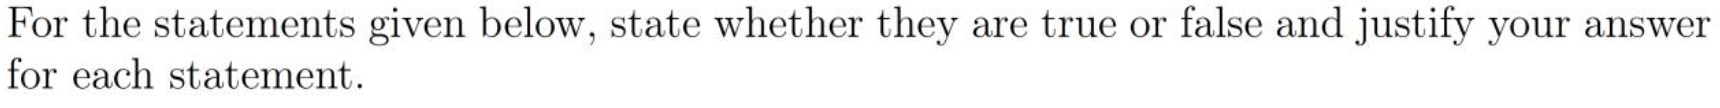

### [✔] 2) The Hilbert transform of a triangular wave signal is another triangular wave signal

Answer: FALSE.

The Hilbert transform rotates the Fourier coefficients in the complex space which converts the real components into the imaginary component. The quarter-cycle shifted signal is then added to the original signal. In other words, a Hilbert transform takes each frequency component present in the original signal and shifts its phase by $-\frac{\pi }{2}$.

The Hilbert transform of $\mathrm{cos}\left(\theta \right)$ is $\mathrm{sin}\left(\theta \right)$ i.e., a quarter-cycle shift.

        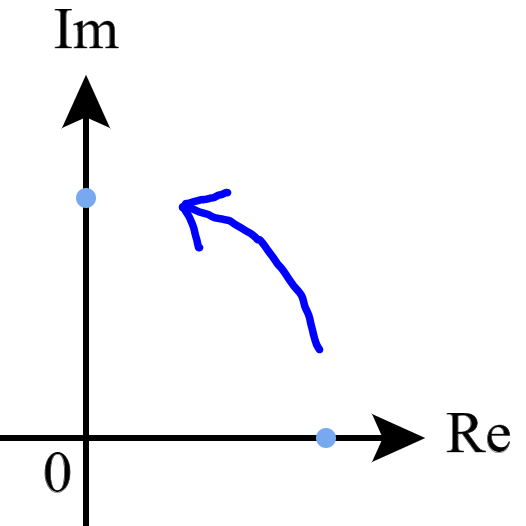

A triangular wave signal can thought of being composed of multiple frequency component. If each of these are shifted by 90 degrees then result is not a triangular wave signal.

We can experiment with it.

N = 256;
n = 0:N-1;
xr = triang(256);
x = hilbert(xr);
plot(n, imag(x), n, real(x))
legend('Real','Imaginary')
title('Hilbert Transformation')
xlim([0, N])

### [✔] 3) Leakage can be reduced in estimates of Power Spectral Density by applying a window function to the data.

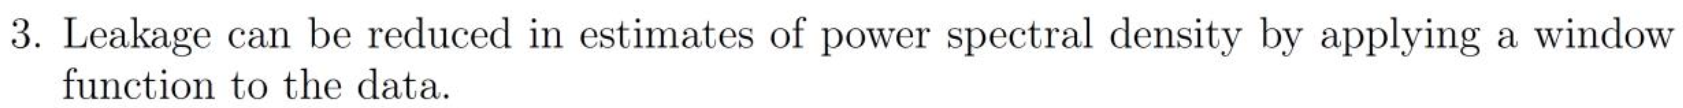

Answer: TRUE.

Leakage is an artefact of an FFT applied to a non-periodic data. Even if a signal is periodic like a sinousoid, when the signal is measured with some interval it can be non-periodic. The issue is that FFT  assumes that the signal is periodic and repeats itself after the measured interval. This is not the case when the data is non-periodic, which contains sharp transitions at the end of each measured interval. These sharp changes have a broad frequency response which lead to spectral leakage. Windows can help *minimize* the effects of leakage by smoothing the time domain signal, but cannot eliminate leakage.

## Problem 4: LMS algorithm

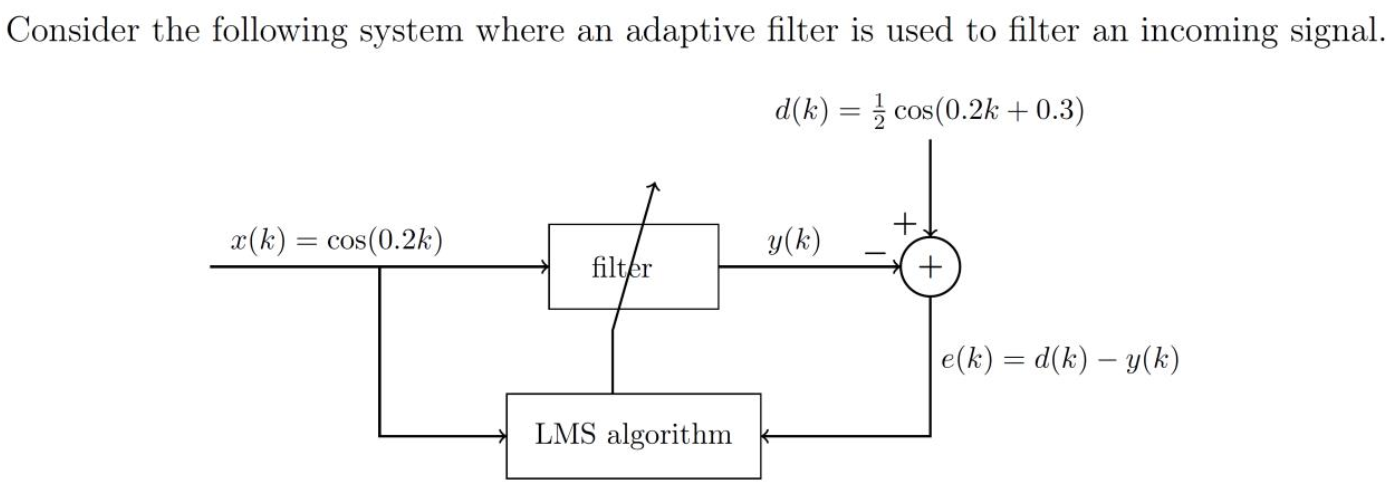

### 1) Compute the coefficients for the first three iterations of the algorithm

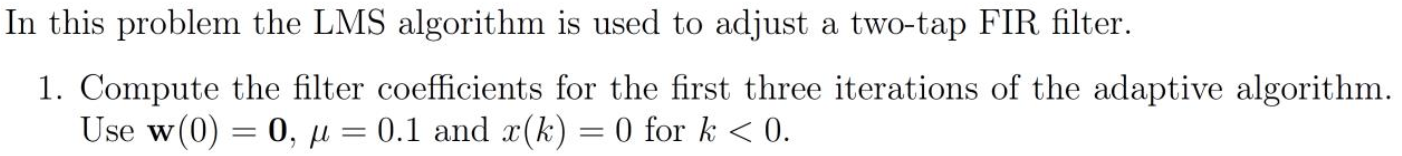

### 2) Discuss the pros and cons of increasing the step size

## Problem 5: Probability Density Functions

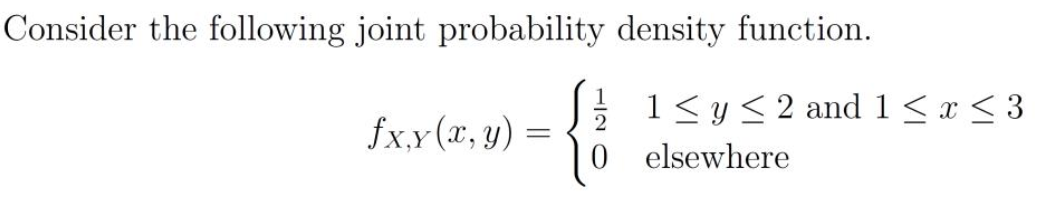

### [✔] 1) Show that the probability density function is valid

Integrate using MATLAB:

syms x y f(x,y) fX(x) fY(y)
f(x,y) = 1/2;
inner = int(f(x,y), x, 1, 3);
outer = int(inner, y, 1, 2)
% Alternative method is to numerically evaluate double integral
fun = @(x,y) 1/2 + 0*(x+y); % Hack: 0*(x+y) is added for MATLAB
integral2(fun, 1, 3, 1, 2)

### [✔] 2) Calculate the marginal probabiltiy density function

The marginal probability density function is given as:

            

The marginal probability for $X$ is given as:

        
$$f_X \left(x\right)=\int_1^2 \frac{1}{2}\;\textrm{dy}={\left\lbrack \frac{1}{2}y\right\rbrack }_1^2 =1-\frac{1}{2}=\frac{1}{2}$$


Check it in MATLAB:

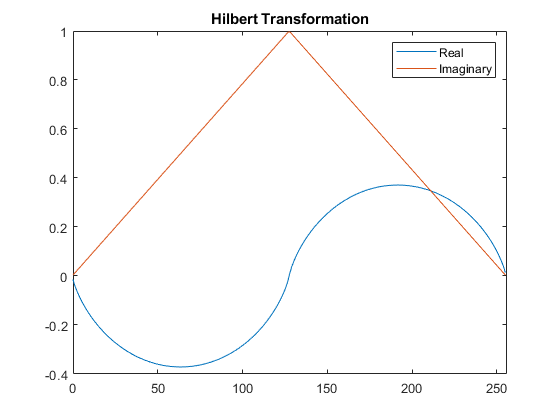

fX(x) = int(f(x,y), y, 1, 2)

% Alternative method
fun = @(y) 1/2 + 0*y; % Hack!
integral(fun, 1, 2)

The marginal probability for $Y$ is given as:

        
$$f_Y \left(y\right)=\int_1^3 \frac{1}{2}\;\textrm{dx}={\left\lbrack \frac{1}{2}x\right\rbrack }_1^3 =\frac{3}{2}-\frac{1}{2}=1$$


fY(y) = int(f(x,y), x, 1, 3)
% Alternative method
fun = @(x) 1/2 + 0*x; % Hack!
integral(fun, 1, 3)

$$outer = 1$$

### [✔] 3) Without calculations, argue whether var(X) or var(Y) is larger

The variance is a measure of the spread of the distribution about its mean value. A large variance indicates that the values of the random variable are spread over a wider interval about the mean. In this problem, $X$ has a wider span of possible values. Therefore, $\mathrm{var}\left(X\right)>\mathrm{var}\left(Y\right)$.

### [✔] 4) Show that X and Y are uncorrelated

Two random variables are uncorrelated if 

        $\mathrm{cov}\left(X,Y\right)=E\left(\mathrm{XY}\right)-E\left\lbrack X\right\rbrack E\left\lbrack Y\right\rbrack =0$   or   $E\left\lbrack \mathrm{XY}\right\rbrack =E\left\lbrack X\right\rbrack E\left\lbrack Y\right\rbrack$

The simplest way to show that $X$ and $Y$ are uncorrelated is if the two random variables are independent.

Two random variables $X$ and $Y$ are said to be independent if:

        
$$f_{X,Y} \left(x,y\right)=f_X \left(x\right)f_Y \left(y\right)$$


The joint probability is given as:

        
$$f_{X,Y} \left(x,y\right)=\frac{1}{2}$$


The marginal probability for $X$ is given as:

        
$$f_X \left(x\right)=\int_1^2 \frac{1}{2}\;\textrm{dy}={\left\lbrack \frac{1}{2}y\right\rbrack }_1^2 =1-\frac{1}{2}=\frac{1}{2}$$


The marginal probability for $Y$ is given as:

        
$$f_Y \left(y\right)=\int_1^3 \frac{1}{2}\;\textrm{dx}={\left\lbrack \frac{1}{2}x\right\rbrack }_1^3 =\frac{3}{2}-\frac{1}{2}=1$$


Since they are the random variables $X$ and $Y$ are indepedent they are also uncorrelated.

Another approach involves computing the covariance and showing that 

        
$$\mathrm{cov}\left(X,Y\right)=E\left(\mathrm{XY}\right)-E\left\lbrack X\right\rbrack E\left\lbrack Y\right\rbrack =0$$


We compute $E\left\lbrack X\right\rbrack$

        
$$E\left\lbrack X\right\rbrack =\int_{-\infty }^{\infty } x\;f_X \left(x\right)\;\mathrm{dx}=\int_1^3 \frac{1}{2}x\;\;\mathrm{dx}={\left\lbrack \begin{array}{c}
\frac{1}{4}x^2 
\end{array}\right\rbrack }_1^3 =\frac{1}{4}{\left(3\right)}^2 -\frac{1}{4}{\left(1\right)}^2 =2$$


Check in MATLAB:

EX = int(f(x,y)*x, x, 1, 3)
% Alternative method

ans = 1

fun = @(x) 1/2*x;
integral(fun, 1, 3)

We compute $E\left\lbrack Y\right\rbrack$

        
$$E\left\lbrack Y\right\rbrack =\int_{-\infty }^{\infty } y\;f_Y \left(y\right)\;\textrm{dy}=\int_1^2 y\;\;\textrm{dy}={\left\lbrack \begin{array}{c}
\frac{1}{2}y^2 
\end{array}\right\rbrack }_1^2 =\frac{1}{2}{\left(2\right)}^2 -\frac{1}{2}=\frac{3}{2}$$


EY = int(fY(y)*y, y, 1, 2)

$$fX(x) = \frac{1}{2}$$

% Alternative method
fun = @(y) y;
integral(fun, 1, 2)

ans = 0.5000

We compute $E\left\lbrack \mathrm{XY}\right\rbrack$:

        
$$E\left\lbrack \mathrm{XY}\right\rbrack =\int_{-\infty }^{\infty } \int_{-\infty }^{\infty } xy\;f_{X,Y} \left(x,y\right)\;\textrm{dy}\;\textrm{dx}$$


        
$$E\left\lbrack \textrm{XY}\right\rbrack =\int_1^3 \left(\int_1^2 \frac{1}{2}xy\;\;\textrm{dy}\right)\;\mathrm{dx}$$


First we compute the inner integral:

        
$$\int_1^2 \frac{1}{2}xy\;\;\textrm{dy}={\left\lbrack \begin{array}{c}
\frac{1}{4}{x\;y}^2 
\end{array}\right\rbrack }_1^2 =\frac{1}{4}{x\left(2\right)}^2 -\frac{1}{4}x=\frac{3}{4}x$$


inner = int(x*y*f(x,y), y, 1, 2)

$$fY(y) = 1$$

Next, we compute the outer integral:

        
$$\int_1^3 \frac{3}{4}x\;\;\textrm{dx}={\left\lbrack \begin{array}{c}
\frac{3}{8}x^2 
\end{array}\right\rbrack }_1^3 =\frac{3}{8}{\left(3\right)}^2 -\frac{3}{8}=\frac{27}{8}-\frac{3}{8}=\frac{24}{8}=3$$


EXY = int(inner, x, 1, 3)

Two random variables are uncorrelated if the covariance $\textrm{cov}\left(X,Y\right)=E\left\lbrack \mathrm{XY}\right\rbrack -E\left\lbrack X\right\rbrack E\left\lbrack Y\right\rbrack =0$.

EXY - EX * EY

ans = 1.0000

$$EX = 2$$

ans = 2

$$EY = \frac{3}{2}$$

ans = 1.5000

$$inner = \frac{3\,x}{4}$$

$$EXY = 3$$

$$ans = 0$$

Since $\textrm{cov}\left(X,Y\right)=E\left\lbrack \textrm{XY}\right\rbrack -E\left\lbrack X\right\rbrack E\left\lbrack Y\right\rbrack =0$ then $X$ and $Y$ are uncorrelated.